clear; close;
ones([1, 2]);

time = 0 : 0.01 : 10;
x0 = [0;0;0];
x = zeros(length(time), 3);

Earth;
F = [0; 0; 0];
a = F./(m*w0*R0)

a =      0
     0
     0



r = sqrt((x(1) + 1)^2 + x(2)^2 + x(3)^2);
dx(1) = x(4);
dx(2) = x(5);
dx(3) = x(6);
dx(4) = 2*x(5) + (1 + x(1))*(1 - r^(-3)) + a(1);
dx(5) = -2*x(4) + x(2)*(1 - r^(-3)) + a(2);
dx(6) = -x(3)*r^(-3) + a(3);


u = [[0;0] [0;0] [0;0]];
MDNS = 100;
size(u)

ans =      2     3



%Polozenie poczatkowe wzgledem Ziemi
Rz = 6.37314*1e6;
x0z = [7e5; 0; 0] + Rz;

v0z = [0 ;7.9196 *1e3; 0];
x0z = [x0z; v0z];

[x0sk, v0sk] = r2x_transform(x0z(1:3), x0z(4:6), 0)

x0sk =    -0.8326
    0.1509
    0.1509


v0sk =     0.1509
    2.4106
         0


tau = [1 100*pi]';

Rz = 6.37314*1e6;
R0 = 7e5 + Rz%4.2242e7/2

R0 = 7073140

x0 = [R0;0;0];

rhat = norm(x0);
r = x0/rhat;

G = 6.67e-11;
M = 5.98e24;
    
v0 = sqrt(G*M/R0) * [0; 1; 0];



[x0sk, v0sk] = r2x_transform(x0, v0, 0);
x0 = [x0sk; v0sk]

x0 =    -0.8326
         0
         0
         0
    2.2771
         0


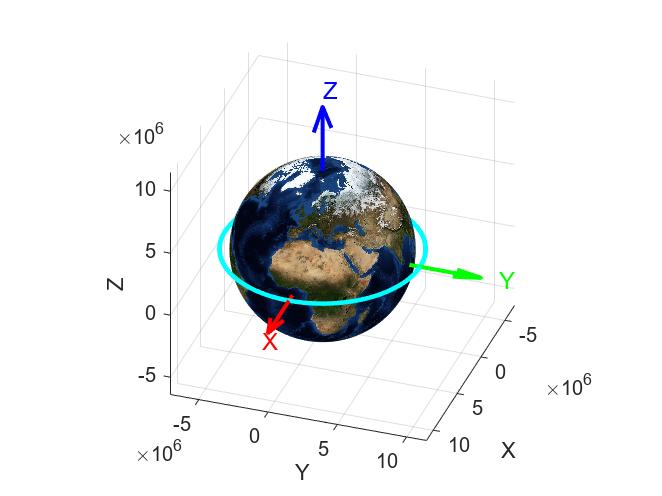

% x0 = [0;0;0;0;0;0]

[t,x,~,~] = get_tx(tau,u,x0,MDNS);


xorb=zeros(length(t),6);
for k=1:length(t)

    [xEarth, vEarth] = x2r_transform(x(k, 1:3)', t(k));
    xorb(k,:)= [xEarth; vEarth];
end 


figure();
printOrbit(xorb(:,1), xorb(:,2), xorb(:,3));

grid on;